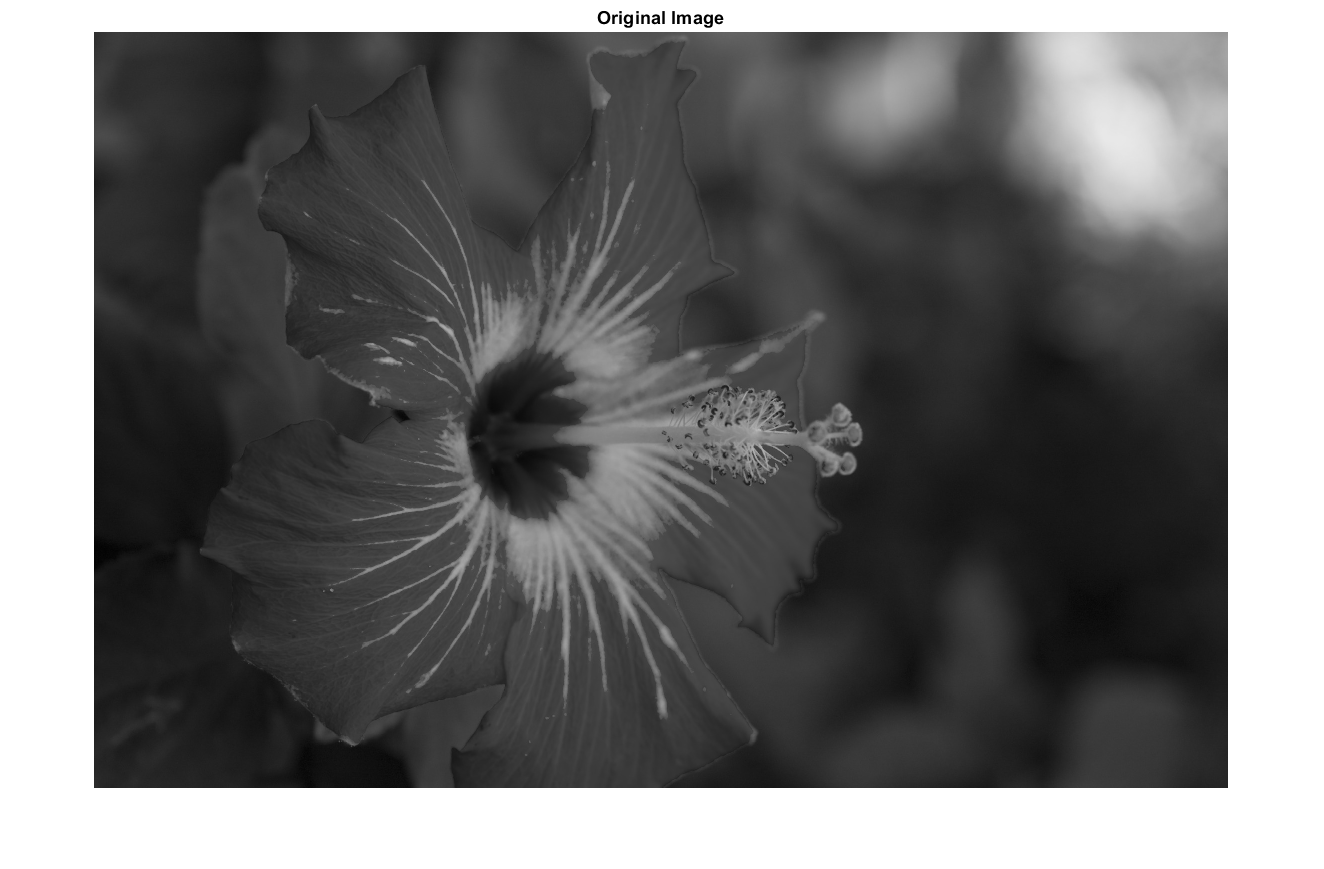

clear;
clc;



% Start of PCA code,

img = imread("flower foveon.jpg");
img_gray = rgb2gray(img);
img_grayD = im2double(img_gray);
figure(1)

imshow(img_grayD)
title('Original Image');

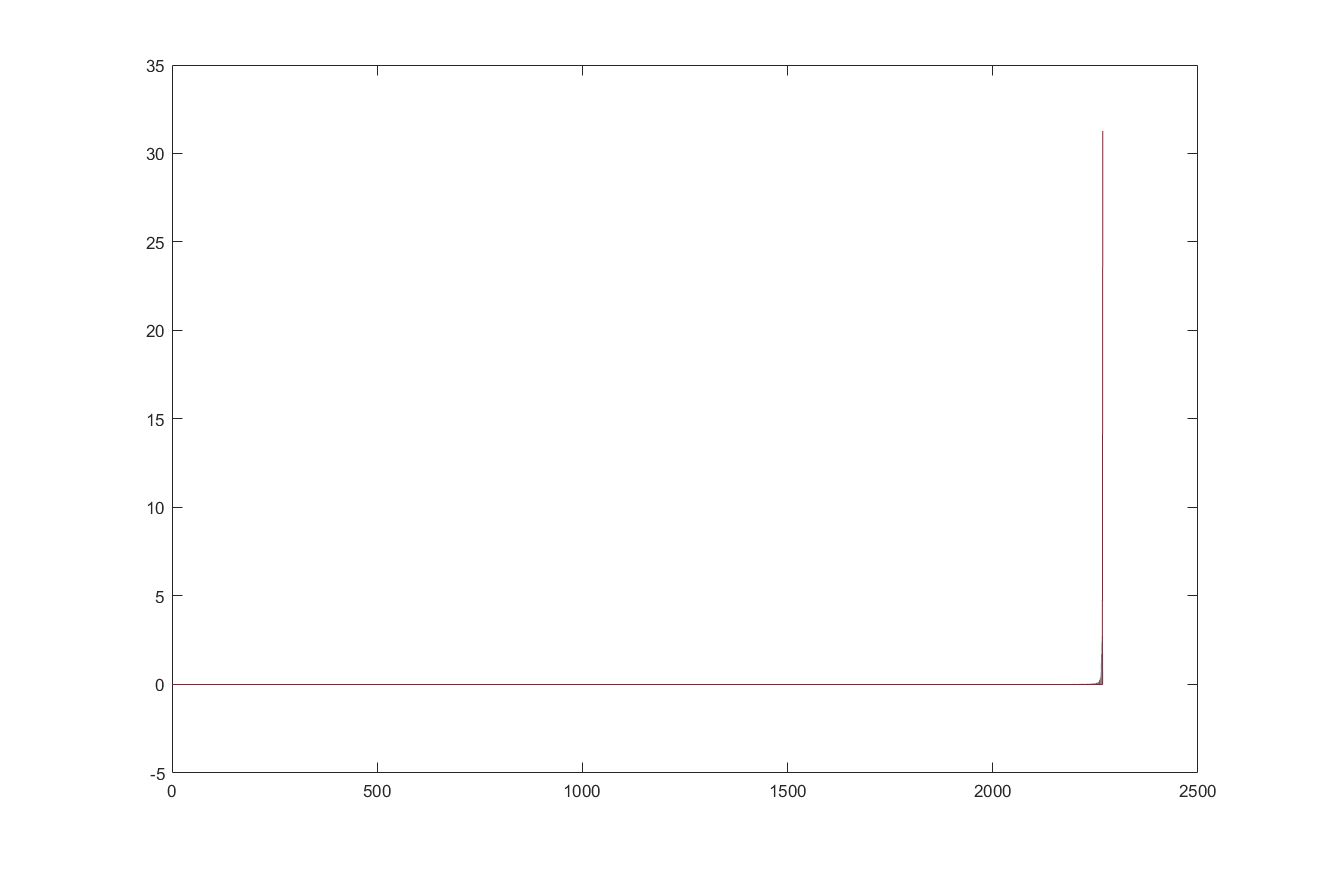


Data_mean = mean(img_grayD);   % row vector containing the mean of each column.
[a, b] = size(img_gray);       % height, width of matrix     
Data_meanNew = repmat(Data_mean,a,1);  % All Column entries are its resp Column mean 
DataAdjust = img_grayD - Data_meanNew; %Standardizing Data
cov_data = cov(DataAdjust);  %Covariance Matrix
[V, D] = eig(cov_data);   %diagonal matrix D of eigenvalues and matrix V whose columns are the corresponding eigenvectors
V_trans = transpose(V);
DataAdjust_trans = transpose(DataAdjust);
FinalData = V_trans * DataAdjust_trans;
% End of PCA code
plot(D)

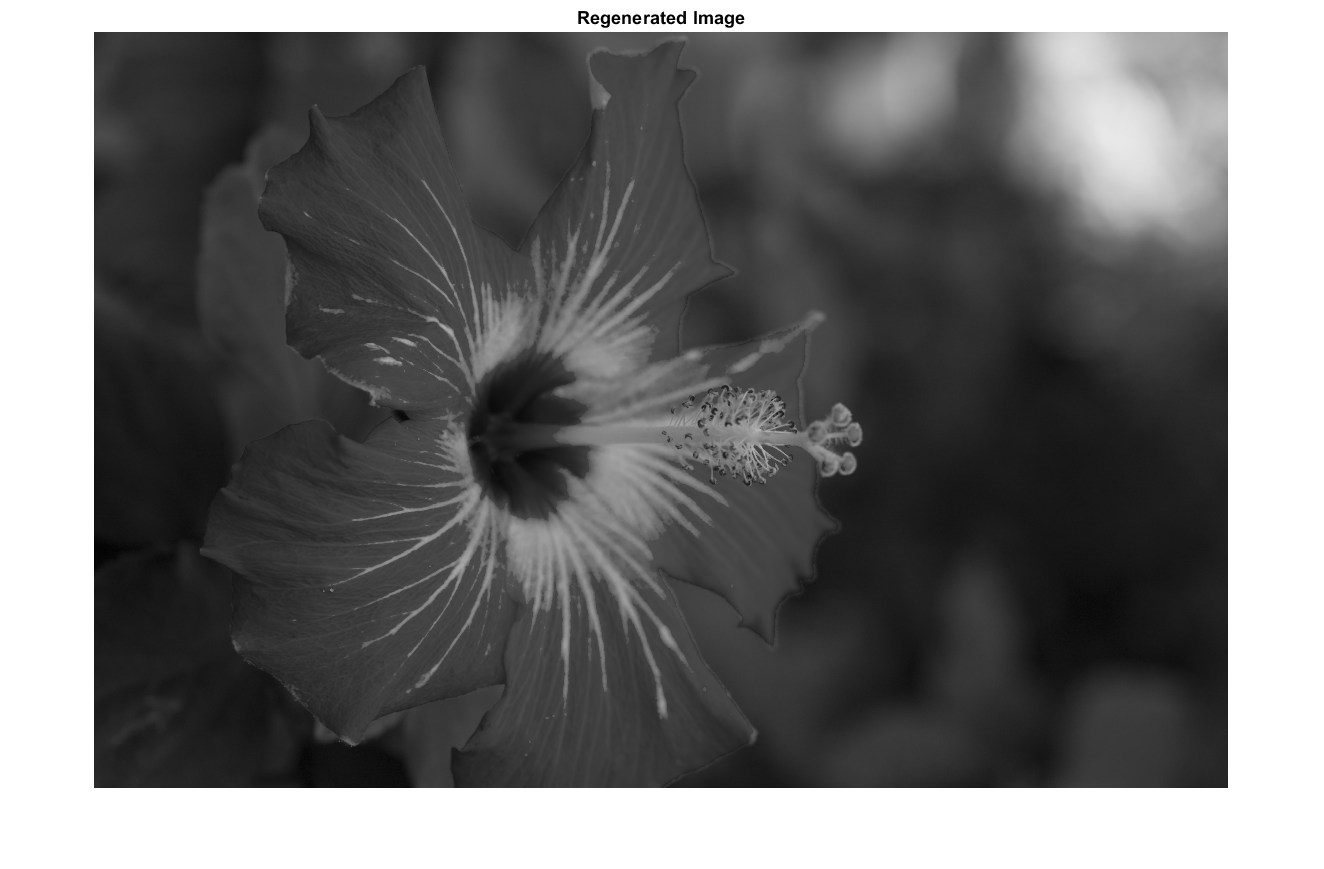

figure
drawnow
% Start of Inverse PCA code,
OriginalData_trans = V_trans \ FinalData;
OriginalData = transpose(OriginalData_trans) + Data_meanNew;
figure,
set(gcf,'numbertitle','off','name','RecoveredImage'),

imshow(OriginalData)
title('Regenerated Image')

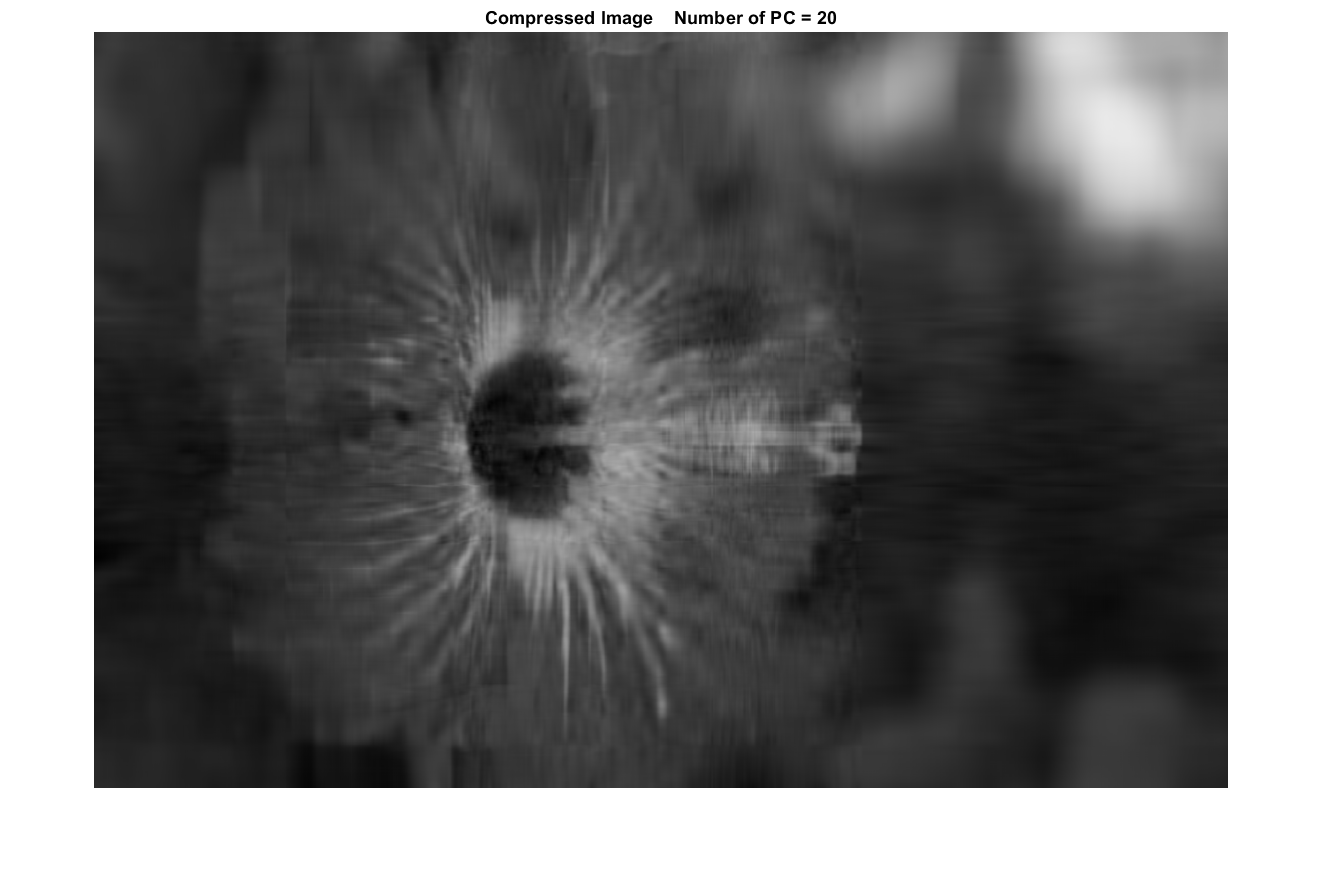

% End of Inverse PCA code

% Image compression
PC=input('Enter number of PC colomuns needed?  ');
PCs = b - PC;
Reduced_V = V;

for i = 1:PCs
    Reduced_V(:,1) =[];
end

Y=Reduced_V'* DataAdjust_trans;
Compressed_Data=Reduced_V*Y;
Compressed_Data = Compressed_Data' + Data_meanNew;
figure,
set(gcf,'numbertitle','off','name','Compressed Image'),
imshow(Compressed_Data)
title(['Compressed Image    Number of PC = ',num2str(PC)])

% End of image compression
imwrite(Compressed_Data,'Compressed_img.jpg');
Compressed_image=imread('Compressed_img.jpg');
n=size(img_gray);
M=n(1);
N=n(2);
MSE = sum(sum((img_gray-Compressed_image).^2))/(M*N);
PSNR = 10*log10(256*256/MSE);
fprintf('\nThe MSE value is %0.4f', MSE);


The MSE value is 12.2574

fprintf('\nThe Peak-SNR value is %0.4f', PSNR);


The Peak-SNR value is 37.2808

CR=dir('Compressed_img.jpg').bytes/dir("flower foveon.jpg").bytes

CR = 0.2017